clc;
clear;

options

frames = 256;
ovrlp = 0.25;
test_size = 300;

**α) Εξαγωγή Συντελεστών LPC**

[x, Fs] = audioread('voice.wav');
X = frame_wind(x, frames, ovrlp);
a_voice = zeros(size(X,1),30);
g_voice = zeros(frames,1);
for i=1:size(X,2)
    [a_voice(i,:),g_voice(:,i)] =lpc_new(X(i),30);
end

**β) Εξαγωγή Συντελεστών MFCC**

i) piano

[x, Fs_piano] = audioread('piano_samples.wav');
mf_piano = mfcc(x,Fs_piano,"NumCoeffs",29);

ii) flute

[x, Fs_flute] = audioread('flute_samples.wav');
mf_flute = mfcc(x,Fs_flute,"NumCoeffs",29);

iii) cello

[x, Fs_cello] = audioread('cello_samples.wav');
mf_cello = mfcc(x,Fs_cello,"NumCoeffs",29);

iv) e_guitar

[x, Fs_guitar] = audioread('e_guitar_samples.wav');
mf_guitar = mfcc(x,Fs_guitar,"NumCoeffs",29);

**γ) Αναγνώριση Μουσικών Οργάνων με συντελεστές MFCC με χρήση προτύπων**

i) piano

m_piano = sum(mf_piano(1:size(mf_piano,1)-test_size,:),1)/(size(mf_piano,1)-test_size);

ii) flute

m_flute = sum(mf_flute(1:size(mf_flute,1)-test_size,:),1)/(size(mf_flute,1)-test_size);

iii) cello

m_cello = sum(mf_cello(1:size(mf_cello,1)-test_size,:),1)/(size(mf_cello,1)-test_size);

iv) e_guitar

m_guitar = sum(mf_guitar(1:size(mf_guitar,1)-test_size,:),1)/(size(mf_guitar,1)-test_size);

Confusion Matrix

CM = zeros(4);

Check the model

i) piano

nRows = size(mf_piano, 1);
for i = (nRows-test_size):nRows
    tmp = zeros(4,1);
    tmp(1) = norm(mf_piano(i,:)-m_piano);
    tmp(2) = norm(mf_piano(i,:)-m_flute);
    tmp(3) = norm(mf_piano(i,:)-m_cello);
    tmp(4) = norm(mf_piano(i,:)-m_guitar);
    [~, index] = min(tmp);
    CM(1,index(1)) = 1 + CM(1,index(1));
end

ii) flute

nRows = size(mf_flute, 1);
for i = (nRows-test_size):nRows
    tmp = zeros(4,1);
    tmp(1) = norm(mf_flute(i,:)-m_piano);
    tmp(2) = norm(mf_flute(i,:)-m_flute);
    tmp(3) = norm(mf_flute(i,:)-m_cello);
    tmp(4) = norm(mf_flute(i,:)-m_guitar);
    [~, index] = min(tmp);
    CM(2,index(1)) = 1 + CM(2,index(1));
end

iii) cello

nRows = size(mf_cello, 1);
for i = (nRows-test_size):nRows
    tmp = zeros(4,1);
    tmp(1) = norm(mf_cello(i,:)-m_piano);
    tmp(2) = norm(mf_cello(i,:)-m_flute);
    tmp(3) = norm(mf_cello(i,:)-m_cello);
    tmp(4) = norm(mf_cello(i,:)-m_guitar);
    [~, index] = min(tmp);
    CM(3,index(1)) = 1 + CM(3,index(1));
end

iv) guitar

nRows = size(mf_guitar, 1);
for i = (nRows-test_size):nRows
    tmp = zeros(4,1);
    tmp(1) = norm(mf_guitar(i,:)-m_piano);
    tmp(2) = norm(mf_guitar(i,:)-m_flute);
    tmp(3) = norm(mf_guitar(i,:)-m_cello);
    tmp(4) = norm(mf_guitar(i,:)-m_guitar);
    [~, index] = min(tmp);
    CM(4,index(1)) = 1 + CM(4,index(1));
end

1. Ακρίβεια αναγνώρισης για κάθε μουσικό όργανο

i) piano

piano_accuracy = CM(1, 1) / sum(CM(1, :))

piano_accuracy = 1

ii) flute

flute_accuracy = CM(2, 2) / sum(CM(2, :))

flute_accuracy = 0.6977

iii) cello

cello_accuracy = CM(3, 3) / sum(CM(3, :))

cello_accuracy = 1

iv) guitar

guitar_accuracy = CM(4, 4) / sum(CM(4, :))

guitar_accuracy = 0.8837

2. Συνολική ακρίβεια αναγνώρισης για όλο το σύστημα

accuracy = sum(diag(CM)) / sum(CM(:))

accuracy = 0.8953

3. Πίνακα Σύγχυσης (confusion matrix)

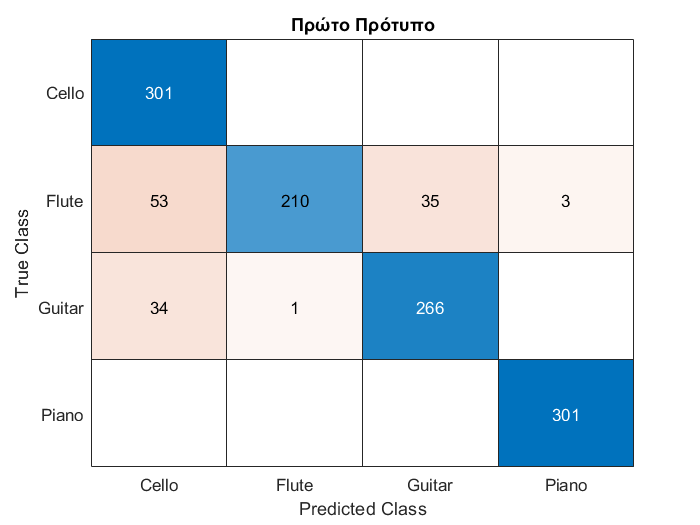

figure
confusionchart(CM,{'Piano', 'Flute', 'Cello','Guitar'})
title("Πρώτο Πρότυπο")

Μπορούμε να δούμε ότι το μοντέλο μπορεί να αναγνωρίσει αν είναι πιάνο ή cello με αρκετή ακρίβεια. Ενώ, στην κιθάρα και στο φλάουτο το μπερδεύει, κυρίως, με το cello. Αυτό μπορεί να συμβαίνει γιατι η κιθάρα και το cello ειναι εγχορδα, ενώ το φλάουτο μπορούν να παράγουν παρόμοιους τόνους.

**δ) Αναγνώριση Μουσικών Οργάνων με συντελεστές MFCC με χρήση Γκαουσιανής κατανομής**

i) piano

m_piano = mean(mf_piano(1:size(mf_piano,1)-test_size,:));
cov_piano = cov(mf_piano(1:size(mf_piano,1)-test_size,:));

ii) flute

m_flute = mean(mf_flute(1:size(mf_flute,1)-test_size,:));
cov_flute = cov(mf_flute(1:size(mf_flute,1)-test_size,:));

iii) cello

m_cello = mean(mf_cello(1:size(mf_cello,1)-test_size,:));
cov_cello = cov(mf_cello(1:size(mf_cello,1)-test_size,:));

iv) e_guitar

m_guitar = mean(mf_guitar(1:size(mf_guitar,1)-test_size,:));
cov_guitar = cov(mf_guitar(1:size(mf_guitar,1)-test_size,:));

Confusion Matrix

CM2 = zeros(4);

Check the model

i) piano

for i = size(mf_piano, 1)-test_size:size(mf_piano, 1)
    like_piano = mvnpdf(mf_piano(i,:), m_piano, cov_piano);
    like_flute = mvnpdf(mf_piano(i,:), m_flute, cov_flute);
    like_cello = mvnpdf(mf_piano(i,:), m_cello, cov_cello);
    like_guitar = mvnpdf(mf_piano(i,:), m_guitar, cov_guitar);
    [~, pred] = max([like_piano, like_flute, like_cello, like_guitar], [], 2);
    CM2(1,pred) = 1 + CM2(1,pred);
end

ii) flute

for i = size(mf_flute, 1)-test_size:size(mf_flute, 1)
    like_piano = mvnpdf(mf_flute(i,:), m_piano, cov_piano);
    like_flute = mvnpdf(mf_flute(i,:), m_flute, cov_flute);
    like_cello = mvnpdf(mf_flute(i,:), m_cello, cov_cello);
    like_guitar = mvnpdf(mf_flute(i,:), m_guitar, cov_guitar);
    [~, pred] = max([like_piano, like_flute, like_cello, like_guitar], [], 2);
    CM2(2,pred) = 1 + CM2(2,pred);
end

iii) cello

for i = size(mf_cello, 1)-test_size:size(mf_cello, 1)
    like_piano = mvnpdf(mf_cello(i,:), m_piano, cov_piano);
    like_flute = mvnpdf(mf_cello(i,:), m_flute, cov_flute);
    like_cello = mvnpdf(mf_cello(i,:), m_cello, cov_cello);
    like_guitar = mvnpdf(mf_cello(i,:), m_guitar, cov_guitar);
    [~, pred] = max([like_piano, like_flute, like_cello, like_guitar], [], 2);
    CM2(3,pred) = 1 + CM2(3,pred);
end

iv) guitar

for i = size(mf_guitar, 1)-test_size:size(mf_guitar, 1)
    like_piano = mvnpdf(mf_guitar(i,:), m_piano, cov_piano);
    like_flute = mvnpdf(mf_guitar(i,:), m_flute, cov_flute);
    like_cello = mvnpdf(mf_guitar(i,:), m_cello, cov_cello);
    like_guitar = mvnpdf(mf_guitar(i,:), m_guitar, cov_guitar);
    [~, pred] = max([like_piano, like_flute, like_cello, like_guitar], [], 2);
    CM2(4,pred) = 1 + CM2(4,pred);
end

1. Ακρίβεια αναγνώρισης για κάθε μουσικό όργανο

i) piano

piano_accuracy2 = CM2(1, 1) / sum(CM2(1, :))

piano_accuracy2 = 0.9801

ii) flute

flute_accuracy2 = CM2(2, 2) / sum(CM2(2, :))

flute_accuracy2 = 0.9934

iii) cello

cello_accuracy2 = CM2(3, 3) / sum(CM2(3, :))

cello_accuracy2 = 1

iv) guitar

guitar_accuracy2 = CM2(4, 4) / sum(CM2(4, :))

guitar_accuracy2 = 0.9834

2. Συνολική ακρίβεια αναγνώρισης για όλο το σύστημα

accuracy2 = sum(diag(CM2)) / sum(CM2(:))

accuracy2 = 0.9892

3. Πίνακα Σύγχυσης (confusion matrix)

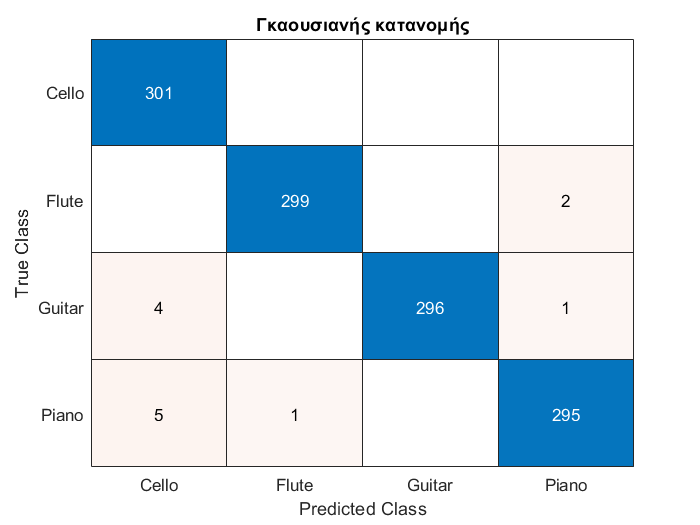

figure
confusionchart(CM2,{'Piano', 'Flute', 'Cello','Guitar'})
title("Γκαουσιανής κατανομής")

Η μέθοδος αυτή έχει καλύτερα αποτελέσματα διότι αυτά τα μουσικά όργανα καταλαμβάνουν διαφορετικό φάσμα συχνότητας και έτσι μπορούμε να φιλτράρουμε με το φάσμα. Στα σημεία που υπάρχει overlap μπορούμε να δούμε το σφαλμα στην κατηγοριοποίηση. Εν τέλει, μπορούμε να συμπεράνουμε οτι το cello και η κιθάρα και το πιάνο πιθανός να βρίσκονται σχετικα κοντά στο φάσμα και το πιάνο να είναι σχετικά κοντά με το φλάουτο και την κιθάρα.

**ε) Σύγκριση συντελεστών LPC με συντελεστές MFCC στην αναγνώριση μουσικών οργάνων**

1) Εξαγωγή Συντελεστών LPC

i) piano

[x, Fs_piano] = audioread('piano_samples.wav');
X = frame_wind(x, frames, ovrlp);
a_piano = zeros(size(X,1),30);
g_piano = zeros(frames,1);
for i=1:size(X,2)
    [a_frame,g_frame] =lpc_new(X(:,i),30);
    a_frame(1) = [];
    a_piano(i,:) = a_frame';
    g_piano(i,:) = g_frame'; 
end

ii) flute

[x, Fs_flute] = audioread('flute_samples.wav');
X = frame_wind(x, frames, ovrlp);
a_flute = zeros(size(X,1),30);
g_flute = zeros(frames,1);
for i=2:size(X,2)
    [a_frame,g_frame] =lpc_new(X(:,i),30);
    a_frame(1) = [];
    a_flute(i,:) = a_frame';
    g_flute(i,:) = g_frame'; 
end

iii) cello

[x, Fs_cello] = audioread('cello_samples.wav');
X = frame_wind(x, frames, ovrlp);
a_cello = zeros(size(X,1),30);
g_cello = zeros(frames,1);
for i=2:size(X,2)
    [a_frame,g_frame] =lpc_new(X(:,i),30);
    a_frame(1) = [];
    a_cello(i,:) = a_frame';
    g_cello(i,:) = g_frame'; 
end

iv) e_guitar

[x, Fs_guitar] = audioread('e_guitar_samples.wav');
X = frame_wind(x, frames, ovrlp);
a_guitar = zeros(size(X,1),30);
g_guitar = zeros(frames,1);
for i=2:size(X,2)
    [a_frame,g_frame] =lpc_new(X(:,i),30);
    a_frame(1) = [];
    a_guitar(i,:) = a_frame';
    g_guitar(i,:) = g_frame'; 
end

2) Αναγνώριση Μουσικών Οργάνων με συντελεστές LPC με χρήση προτύπων

i) piano

ml_piano = sum(a_piano(1:size(a_piano,1)-test_size,:),1)/(size(a_piano,1)-test_size);

ii) flute

ml_flute = sum(a_flute(1:size(a_flute,1)-test_size,:),1)/(size(a_flute,1)-test_size);

iii) cello

ml_cello = sum(a_cello(1:size(a_cello,1)-test_size,:),1)/(size(a_cello,1)-test_size);

iv) e_guitar

ml_guitar = sum(a_guitar(1:size(a_guitar,1)-test_size,:),1)/(size(a_guitar,1)-test_size);

Confusion Matrix

CMa = zeros(4);

Check the model

i) piano

for i = (size(a_piano,1)-test_size):size(a_piano,1)
    tmp = zeros(4,1);
    tmp(1) = norm(a_piano(i,:)-ml_piano);
    tmp(2) = norm(a_piano(i,:)-ml_flute);
    tmp(3) = norm(a_piano(i,:)-ml_cello);
    tmp(4) = norm(a_piano(i,:)-ml_guitar);
    [~, index] = min(tmp);
    CMa(1,index(1)) = 1 + CMa(1,index(1));
end

ii) flute

for i = (size(a_flute,1)-test_size):size(a_flute,1)
    tmp = zeros(4,1);
    tmp(1) = norm(a_flute(i,:)-ml_piano);
    tmp(2) = norm(a_flute(i,:)-ml_flute);
    tmp(3) = norm(a_flute(i,:)-ml_cello);
    tmp(4) = norm(a_flute(i,:)-ml_guitar);
    [~, index] = min(tmp);
    CMa(2,index(1)) = 1 + CMa(2,index(1));
end

iii) cello

for i = (size(a_cello,1)-test_size):size(a_cello,1)
    tmp = zeros(4,1);
    tmp(1) = norm(a_cello(i,:)-ml_piano);
    tmp(2) = norm(a_cello(i,:)-ml_flute);
    tmp(3) = norm(a_cello(i,:)-ml_cello);
    tmp(4) = norm(a_cello(i,:)-ml_guitar);
    [~, index] = min(tmp);
    CMa(3,index(1)) = 1 + CMa(3,index(1));
end

iv) guitar

for i = (size(a_guitar,1)-test_size):size(a_guitar,1)
    tmp = zeros(4,1);
    tmp(1) = norm(a_guitar(i,:)-ml_piano);
    tmp(2) = norm(a_guitar(i,:)-ml_flute);
    tmp(3) = norm(a_guitar(i,:)-ml_cello);
    tmp(4) = norm(a_guitar(i,:)-ml_guitar);
    [~, index] = min(tmp);
    CMa(4,index(1)) = 1 + CMa(4,index(1));
end

1. Ακρίβεια αναγνώρισης για κάθε μουσικό όργανο

i) piano

piano_accuracy_lpc = CMa(1, 1) / sum(CMa(1, :))

piano_accuracy_lpc = 0.0100

ii) flute

flute_accuracy_lpc = CMa(2, 2) / sum(CMa(2, :))

flute_accuracy_lpc = 0.8173

iii) cello

cello_accuracy_lpc = CMa(3, 3) / sum(CMa(3, :))

cello_accuracy_lpc = 0.5515

iv) guitar

guitar_accuracy_lpc = CMa(4, 4) / sum(CMa(4, :))

guitar_accuracy_lpc = 0.6312

2. Συνολική ακρίβεια αναγνώρισης για όλο το σύστημα

accuracy_lpc = sum(diag(CMa)) / sum(CMa(:))

accuracy_lpc = 0.5025

3. Πίνακα Σύγχυσης (confusion matrix)

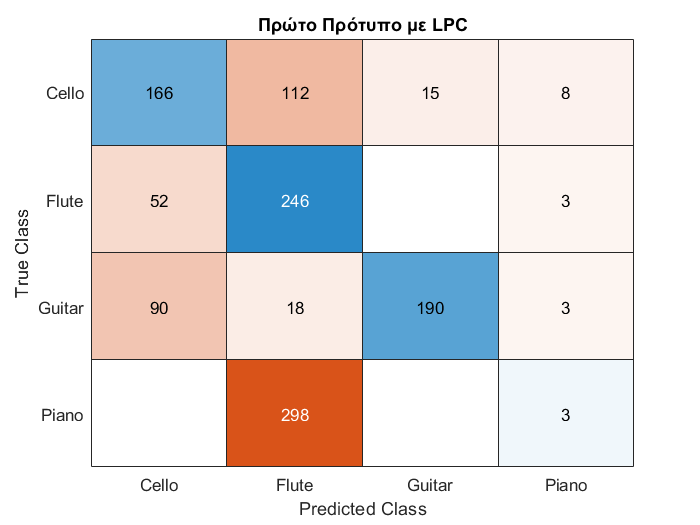

figure
confusionchart(CMa,{'Piano', 'Flute', 'Cello','Guitar'})
title("Πρώτο Πρότυπο με LPC")

3) Αναγνώριση Μουσικών Οργάνων με συντελεστές LPC με χρήση Γκαουσιανής κατανομής

i) piano

ml_piano = mean(a_piano(1:size(a_piano,1)-test_size,:));
covl_piano = cov(a_piano(1:1:size(a_piano,1)-test_size,:));

ii) flute

ml_flute = mean(a_flute(1:size(a_flute,1)-test_size,:));
covl_flute = cov(a_flute(1:size(a_flute,1)-test_size,:));

iii) cello

ml_cello = mean(a_cello(1:size(a_cello,1)-test_size,:));
covl_cello = cov(a_cello(1:size(a_cello,1)-test_size,:));

iv) e_guitar

ml_guitar = mean(a_guitar(1:size(a_guitar,1)-test_size,:));
covl_guitar = cov(a_guitar(1:size(a_guitar,1)-test_size,:));

Confusion Matrix

CM2a = zeros(4);

Check the model

i) piano

for i = (size(a_piano,1)-test_size):size(a_piano,1)
    tmp = zeros(4,1);
    tmp(1) = mvnpdf(a_piano(i,:), ml_piano, covl_piano);
    tmp(2) = mvnpdf(a_piano(i,:), ml_flute, covl_flute);
    tmp(3) = mvnpdf(a_piano(i,:), ml_cello, covl_cello);
    tmp(4) = mvnpdf(a_piano(i,:), ml_guitar, covl_guitar);
    [~, pred] = max(tmp);
    CM2a(1,pred) = 1 + CM2a(1,pred);
end

ii) flute

for i = (size(a_flute,1)-test_size):size(a_flute,1)
    like_piano = mvnpdf(a_flute(i,:), ml_piano, covl_piano);
    like_flute = mvnpdf(a_flute(i,:), ml_flute, covl_flute);
    like_cello = mvnpdf(a_flute(i,:), ml_cello, covl_cello);
    like_guitar = mvnpdf(a_flute(i,:), ml_guitar, covl_guitar);
    [~, pred] = max([like_piano, like_flute, like_cello, like_guitar]);
    CM2a(2,pred) = 1 + CM2a(2,pred);
end

iii) cello

for i = (size(a_cello,1)-test_size):size(a_cello,1)
    like_piano = mvnpdf(a_cello(i,:), ml_piano, covl_piano);
    like_flute = mvnpdf(a_cello(i,:), ml_flute, covl_flute);
    like_cello = mvnpdf(a_cello(i,:), ml_cello, covl_cello);
    like_guitar = mvnpdf(a_cello(i,:), ml_guitar, covl_guitar);
    [~, pred] = max([like_piano, like_flute, like_cello, like_guitar]);
    CM2a(3,pred) = 1 + CM2a(3,pred);
end

iv) guitar

for i = (size(a_guitar,1)-test_size):size(a_guitar,1)
    like_piano = mvnpdf(a_guitar(i,:), ml_piano, covl_piano);
    like_flute = mvnpdf(a_guitar(i,:), ml_flute, covl_flute);
    like_cello = mvnpdf(a_guitar(i,:), ml_cello, covl_cello);
    like_guitar = mvnpdf(a_guitar(i,:), ml_guitar, covl_guitar);
    [~, pred] = max([like_piano, like_flute, like_cello, like_guitar]);
    CM2a(4,pred) = 1 + CM2a(4,pred);
end

1. Ακρίβεια αναγνώρισης για κάθε μουσικό όργανο

i) piano

piano_accuracy2a = CM2a(1, 1) / sum(CM2a(1, :))

piano_accuracy2a = 0.4551

ii) flute

flute_accuracy2a = CM2a(2, 2) / sum(CM2a(2, :))

flute_accuracy2a = 0.9801

iii) cello

cello_accuracy2a = CM2a(3, 3) / sum(CM2a(3, :))

cello_accuracy2a = 0.9502

iv) guitar

guitar_accuracy2a = CM2a(4, 4) / sum(CM2a(4, :))

guitar_accuracy2a = 0.9900

2. Συνολική ακρίβεια αναγνώρισης για όλο το σύστημα

accuracy2a = sum(diag(CM2a)) / sum(CM2a(:))

accuracy2a = 0.8439

3. Πίνακα Σύγχυσης (confusion matrix)

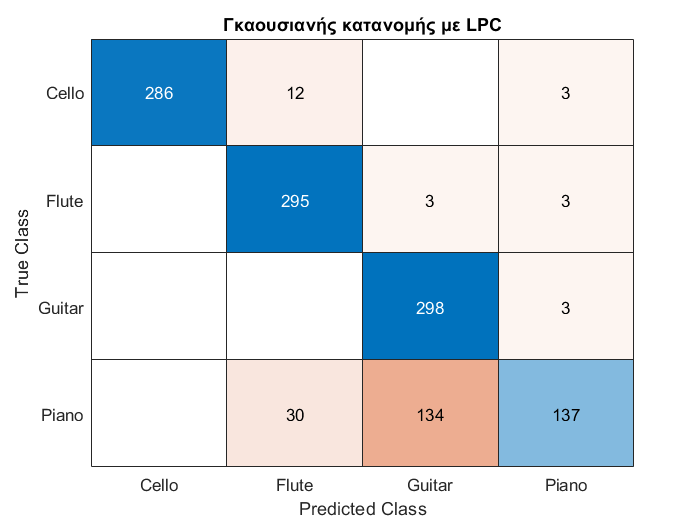

figure
confusionchart(CM2a,{'Piano', 'Flute', 'Cello','Guitar'})
title("Γκαουσιανής κατανομής με LPC")

Όπως μπορούμε να δούμε τα αποτελέσματα είναι αυτά που περιμέναμε να δούμε, διότι το LPC είναι φτιαγμένο ειδικά για την ανθρώπινη φωνή, ενώ ο MFCC είναι πιο γενικό. Για αυτό υπάρχει και η τεράστιά διαφορά στην ακρίβεια των αποτελεσμάτων.